imgarray_dark=loadRAWinArray_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_dsnu',640,480);
imgarray_50=loadRAWinArray_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_prnu',640,480);

images_dark=cellarray_to_3d_matrix(imgarray_dark);
images_50=cellarray_to_3d_matrix(imgarray_50);

% K=0.098;
% tic;
% [DSNU,PRNU,sv_50,sv_dark] = DSNU_PRNU_3dmat(images_dark,images_50,K)
% toc;

imgarray_mv=loadRAWinArray_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_mv',640,480);

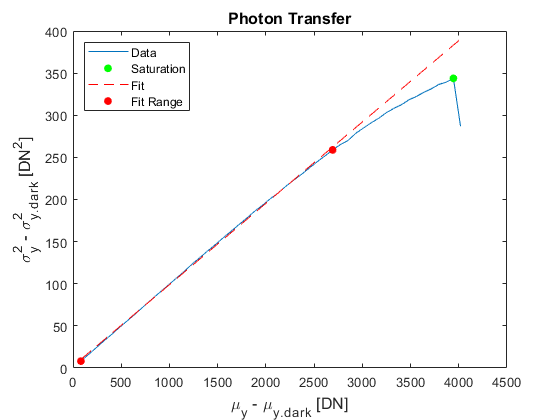

mean_dark = 29.4063

var_dark = 9.0780

K = 0.0966

[mean_dark,var_dark,K] = photonTransfer_curve_EMVA1288_mono(imgarray_mv)

temp_dark=compute_temporaldarknoise(var_dark,(1/12),K)

temp_dark = 31.0596

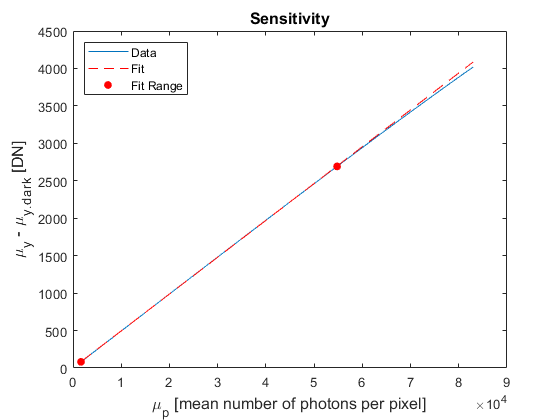

R = 0.0492

p_sat = 8.1323e+04

[R,p_sat] = sensitivity_curve_mono(imgarray_mv,1659.66)

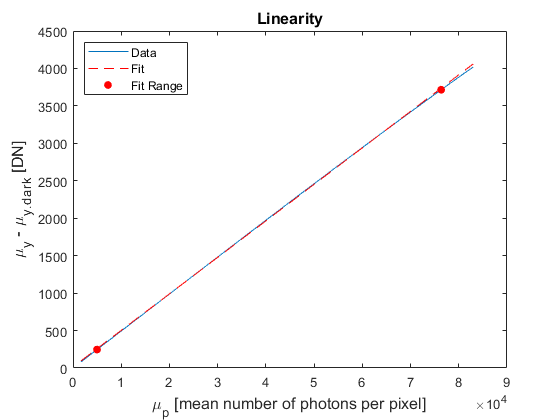

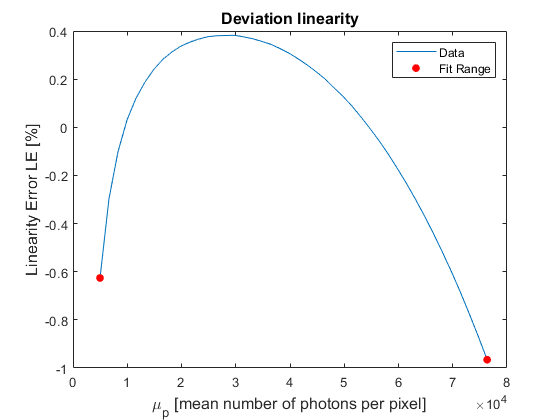

LE_min = -0.9656

LE_max = 0.3818

[LE_min,LE_max] = linearity(imgarray_mv,1659.66)

[DSNU,PRNU,sv_50,sv_dark,avg_img_dark,avg_img_50,var_stack_dark,var_stack_50] = DSNU_PRNU_3dmat(images_dark,images_50,K)

DSNU = 22.0316

PRNU = 0.9669

sv_50 = 395.9462

sv_dark = 4.5257

avg_img_dark =    30.8100   32.2200   29.6400   31.0900   31.0400   32.0400   30.6700   30.8500   25.1700   30.0400   32.6100   28.1000   28.7600   23.3800   27.0500   31.3000   29.4300   27.9300   24.1400   29.5000   31.6700   29.0800   30.8400   27.7400   31.8600   30.8100   31.7800   28.4700   28.4100   28.6900   31.6300   31.6300   27.8300   27.5700   29.1200   26.8800   30.6800   25.8500   25.3500   29.7300   31.7900   28.8700   27.4700   26.7600   31.0600   31.7000   33.9100   28.8100   29.6900   32.3400
   31.0100   27.5300   28.7400   29.6400   30.9600   27.6800   29.0400   28.4100   33.1300   29.8500   29.7500   26.9300   27.8200   28.2200   31.4300   27.3400   30.1800   27.0400   29.5700   32.9200   31.5600   29.2800   29.8000   31.3900   33.6800   31.6400   28.4500   30.1800   29.7800   29.4400   30.4000   27.5800   27.5700   27.2900   31.8200   28.5100   27.1600   29.7700   27.0100   26.4400   30.3600   27.6300   29.9900   30.1900   32.7800   33.4600   28.5100   30.1900   3

avg_img_50 = 	1.0e+03 *

    1.9971    2.0193    2.0210    2.0232    2.0008    2.0058    2.0246    2.0085    2.0176    2.0115    2.0217    2.0050    2.0089    2.0204    2.0148    2.0112    2.0169    2.0140    2.0213    2.0034    2.0164    2.0197    2.0110    2.0250    2.0286    1.9996    2.0187    2.0165    2.0176    2.0326    2.0131    2.0265    2.0294    2.0260    2.0174    2.0168    2.0113    2.0171    2.0129    2.0353    2.0372    2.0037    2.0062    2.0171    2.0093    2.0280    2.0226    2.0446    2.0299    2.0208
    2.0234    2.0185    2.0140    1.9993    2.0149    2.0188    2.0049    2.0035    1.9950    2.0268    2.0206    2.0018    2.0069    2.0099    2.0122    2.0004    2.0151    2.0122    2.0232    2.0145    2.0205    2.0088    2.0121    2.0246    2.0078    2.0245    2.0116    2.0186    2.0113    2.0175    2.0237    2.0187    2.0291    2.0140    2.0112    2.0223    2.0119    2.0414    2.0082    2.0208    2.0236    2.0345    2.0326    2.0128    2.0368    2.0375    2.0183    

var_stack_dark = 9.0819

var_stack_50 = 210.0982


p_min= absolute_sensitivity_threshold(R/K,var_dark,K)

p_min = 62.2267


e_sat = saturation_capacity(R/K,p_sat)

e_sat = 4.1432e+04

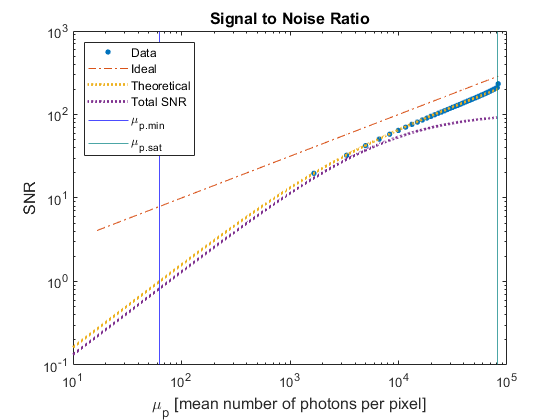

SNR_max = 203.5497

DR = 1.3069e+03

[SNR_max,DR] = plot_SNR(imgarray_mv,1659.66,p_min,p_sat,e_sat,temp_dark,1/12,K,R/K,DSNU,PRNU)

output=fourier_eq49(avg_img_dark)

output =   -1.5088 - 0.7152i   1.5905 + 1.4013i   0.9411 - 0.2691i   0.4283 - 1.0869i   0.1743 + 0.4176i   1.1342 + 1.1869i   0.8930 + 0.0044i   0.4918 + 1.5841i   1.0260 + 0.6981i  -0.9818 - 0.4752i   1.8437 - 0.5101i  -0.3645 - 0.2390i   0.9022 - 3.1817i   1.5590 + 0.1986i   3.1749 + 0.0521i   0.3165 - 1.2467i  -0.0782 + 0.7006i   1.8330 + 1.8896i  14.6989 + 5.8858i  -2.9276 - 0.6409i  -1.3274 - 2.4867i  -1.4851 - 0.9368i  -2.0807 - 0.4351i  -2.1765 + 1.0045i   0.5521 - 0.4550i  -0.4329 - 0.8535i  -0.6935 - 1.8043i  -1.7601 - 0.6783i   0.5924 + 0.0104i   0.9589 + 0.6165i  -0.3661 + 1.5297i   0.3828 + 0.9175i   0.6541 - 0.3427i  -2.7689 + 1.8567i  -1.4166 - 3.0059i  -0.4344 + 1.6760i   0.2450 + 0.8801i  -0.4253 + 0.5452i  -2.1856 + 0.3186i  -0.8056 - 0.5146i   2.0980 - 0.7403i  -1.6167 + 0.8550i  -1.1876 - 0.4365i  -0.7889 - 0.4731i   0.1990 - 0.1188i   0.1039 - 1.7964i   0.4561 + 0.6143i  -0.2500 - 0.7349i   0.0762 - 0.3941i  -0.3061 - 0.3612i
   0.0528 - 0.7449i  -0.6476 - 1.6708i  

p=power_spectrum_eq50(output)

p =     2.4406    2.3267    2.3652    2.3730    2.2643    2.4798    2.4893    2.6127    2.5452    2.6216    2.6346    2.6621    2.5722    2.7349    3.0013    3.2444    4.2225    8.5878  238.5550   16.9288    5.1715    3.7259    3.1025    2.6589    2.6543    2.4654    2.5405    2.5912    2.3469    2.4210    2.3963    2.7154    2.3299    2.4416    2.2458    2.4353    2.4391    2.2318    2.3795    2.1756    2.3157    2.5376    2.5031    2.3188    2.2875    2.5522    2.3587    2.4052    2.2187    2.2346


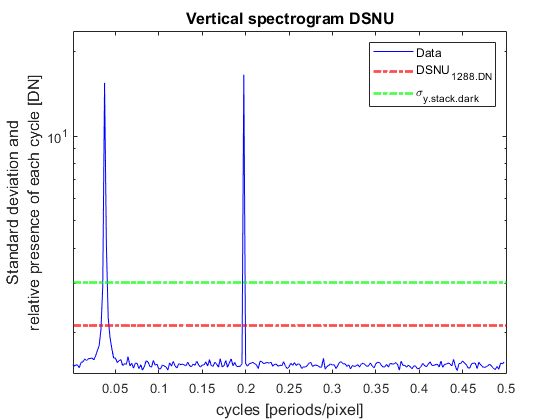

var_ = 0

var_=spectrogram(avg_img_dark,'vertical','DSNU',DSNU,var_stack_dark,K)

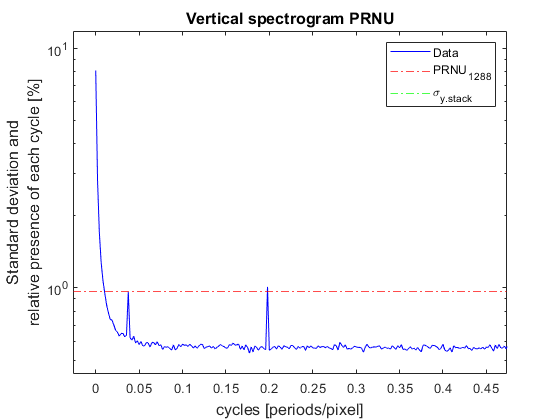

var_2 = 0

var_2=spectrogram(avg_img_50,'vertical','PRNU',PRNU,var_stack_50,K)